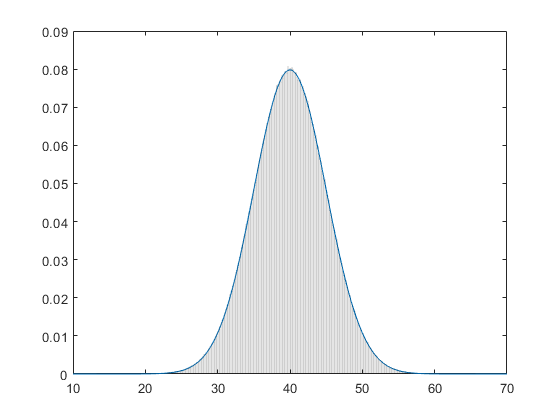

% Reproducing 3. Simple extreme value problem from E.J. OBrien et al.

% Initial commands
clear, clc, close all

% Create a normal distribution according to the example
pd = makedist('Normal','mu',40,'sigma',5);
% The number of observations per day
nperd = 3000;

% The total number of workdays (for 3 samples)
wd = [200 500 1000];

% Pour l'instant, we start with the third sample
D = random(pd,nperd,wd(3));

% Plot the original data in histogram form along with matching normal curve
fOV = figure('Name','Overview');
x = 10:0.1:70;
y = pdf(pd,x);
plot(x,y)
hold on
histogram(D,'EdgeAlpha',0.1,'FaceColor','none','normalization','pdf')

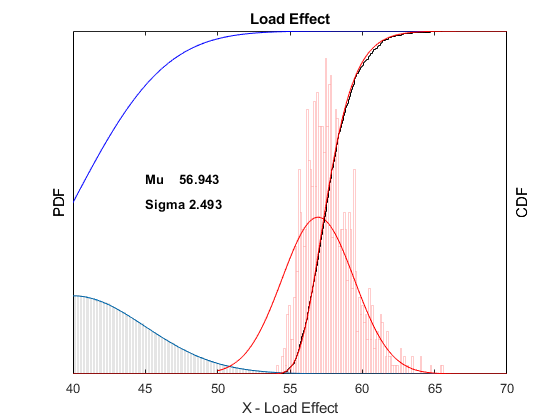





% Compute daily maximum data
DMax = max(D)';

% Plot Histogram of Maxes on the same plot
histogram(DMax,100,'EdgeColor','r','EdgeAlpha',0.2,'FaceColor','none','normalization','pdf')
ylabel('PDF')
set(gca,'YTick', [])
xlabel('X - Load Effect')
xlim([40 70])

% Emperical cdf (ecdf) is a function that ranks data points in a sample (DMaxR) and gives 
% the probability of non-exceedance (DMaxCDF)... it plots when given no variable
[DMaxeCDF, DMaxR] = ecdf(DMax); DMaxR = DMaxR';
% Plot the CDF on the same plot, but with a new y-axis
yyaxis right
stairs(DMaxR,DMaxeCDF,'k')
title('Load Effect')
ylabel('CDF')
set(gca,'YTick',[],'YColor','k')

% Now the trick is that we want to do a least squares fit for only the top 30% of
% values from the 1000 daily maximum LE's. We do this for POT, GEV, Box-Cox, and Normal dists.
% We do NOT take the top 30% and treat them as a new sample...

% For Normal and Weibull, we use probability paper plots (easily linearized)
% Normal probability paper plot
% Create Vector of Indices
i = 1:length(DMaxR);
% Create Vector of Probabilities
PrI = i/(i(end)+1);
% Get the Standard Normal Values for these Probabilities
NIPrI = norminv(PrI);
% Plot the Standard Normal Values to the Actual Maxes
% figure
x = NIPrI;
y = DMaxR;
% scatter(x,y);

% Fit data to line; Coeff(1) = Sigma, Coeff(2) = Mu... NOT THE CORRECT METHOD
% Coeff = polyfit(x, y, 1);
% % Plot the line and label it
% xFit = linspace(min(x), max(x), 1000);
% yFit = polyval(Coeff , xFit);
% hold on;
% plot(xFit, yFit, 'r-', 'LineWidth', 2);
% grid on;
% ylabel('X - Load Effect')
% xlabel('Standard Normal')
% text(-1,62,sprintf('Mu    %.3f',Coeff(2)),'FontSize',10,'FontWeight','bold','Color','k')
% text(-1,61,sprintf('Sigma %.3f',Coeff(1)),'FontSize',10,'FontWeight','bold','Color','k')

% Fit top 30% of data to line; Coeff(1) = Sigma, Coeff(2) = Mu... THE CORRECT METHOD
% Calculate cut-off index COi and value COv
COi = round(length(DMax)*0.7);
COv = DMax(COi);
Coeff = polyfit(x(COi:end), y(COi:end), 1);
xFit = linspace(min(x), max(x), 1000);
yFit = polyval(Coeff , xFit);
hold on;
plot(xFit, yFit, 'r-', 'LineWidth', 2);
text(1,56,sprintf('Mu    %.3f',Coeff(2)),'FontSize',10,'FontWeight','bold','Color','k')
text(1,55,sprintf('Sigma %.3f',Coeff(1)),'FontSize',10,'FontWeight','bold','Color','k')

% Create a distribution out of the second fit (top 30%) and plot normal curve
% on original figure
figure(fOV)
npdx = makedist('normal','mu', Coeff(2),'sigma',Coeff(1));
x = 50:0.1:70;
y = pdf(npdx,x);
Y = cdf(npdx,x);
hold on
yyaxis left
plot(x,y,'r-')
text(45,0.200,sprintf('Mu    %.3f',npdx.mu),'FontSize',10,'FontWeight','bold','Color','k')
text(45,0.175,sprintf('Sigma %.3f',npdx.sigma),'FontSize',10,'FontWeight','bold','Color','k')

% % Weibull Probability Paper Plot
% x = log(-log(1-PrI));
% y = log(DMaxR);
% figure
% scatter(x,y);
% Coeff = polyfit(x(COi:end), y(COi:end), 1);
% b = 1/Coeff(1);
% a = exp(Coeff(2));
% xFit = linspace(min(x), max(x), 1000);
% yFit = polyval(Coeff , xFit);
% hold on;
% plot(xFit, yFit, 'r-', 'LineWidth', 2);
% text(0,3.90,sprintf('Scale  %.3f',a),'FontSize',10,'FontWeight','bold','Color','k')
% text(0,3.85,sprintf('Shape %.3f',b),'FontSize',10,'FontWeight','bold','Color','k')
% grid on;
% ylabel('X - Load Effect')
% xlabel('Standard Normal')
% 
% % Note that a and b are swaped with Alpha and Beta!
% figure('Name','Overview')
% npdx = makedist('weibull','a', a,'b',b);
% x = 50:0.1:70;
% y = pdf(npdx,x);
% Yx = cdf(npdx,x);
% hold on
% yyaxis left
% plot(x,y,'g-')
% text(62,0.200,sprintf('Scale   %.3f',npdx.a),'FontSize',10,'FontWeight','bold','Color','k')
% text(62,0.175,sprintf('Shape %.3f',npdx.b),'FontSize',10,'FontWeight','bold','Color','k')

% The paper by EJOBrien uses Gumbel probability paper
% The Gumbel probability paper involves taking the -log(-log(CDF))
% Plot the original data
fPP = figure('Name','Probability Paper');
scatter(DMaxR,-log(-log(DMaxeCDF)),7,'k','filled','DisplayName','Daily Max Data');
ylabel('-log(-log(Probability of non-exceedance))')
xlabel('X - Load Effect')
% Plot 
hold on
% Plot Normal
plot(x(x > COv & x < max(DMax)),-log(-log(Y(x > COv & x < max(DMax)))),'DisplayName','Normal')
% Plot Weibull
% plot(x(x > COv & x < max(DMax)),-log(-log(Yx(x > COv & x < max(DMax)))),'DisplayName','Weibull')
xlim([53.7 64.9])
ylim([-2 8.2])
box on
xticks(54:2:64)
yticks(-1:8)

% Paretotails... still have to figure this one out
pfit = paretotails(DMax,0.1,0.7);
hold on
Y = cdf(pfit,x);
plot(x(x > COv & x < max(DMax)),-log(-log(Y(x > COv & x < max(DMax)))),'DisplayName','Pareto')

% Plot the exact CDF of both the original data, and the maximums
figure(fOV)
x = 10:0.1:70;
DCDF = cdf(pd,x);
yyaxis right
plot(x,DCDF,'b-')
% DMaxCDF is the exact distribution... see p 188 of Ang and Tang
DMaxCDF = DCDF.^3000;
plot(x,DMaxCDF,'r-')

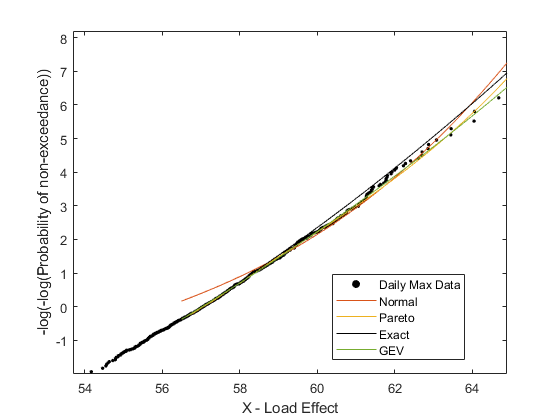


% Add this exact CDF to the probability paper plot
figure(fPP)
plot(x(x > COv & x < max(DMax)),-log(-log(DMaxCDF(x > COv & x < max(DMax)))),'k-','DisplayName','Exact')

legend('location','best')

% Create function to solve for parameters of GEV distribution fit to tail
fnGEV = @(param) sum((gevcdf(DMaxR(COi:end),param(1),param(2),param(3)) - DMaxeCDF(COi:end)').^2);
% Use gevfit to generate an initial guess
B = gevfit(DMax);
% Solve for parameters using fminsearch
A =  fminsearch(fnGEV,B);

x = 50:0.1:70;
Y = gevcdf(x,A(1),A(2),A(3));
% figure(fPP)
% plot(x(x > COv & x < max(DMax)),-log(-log(Y(x > COv & x < max(DMax)))))

figure(fPP)
x = 50:0.1:70;
Y = gevcdf(x,B(1),B(2),B(3));
plot(x(x > COv & x < max(DMax)),-log(-log(Y(x > COv & x < max(DMax)))),'DisplayName','GEV')

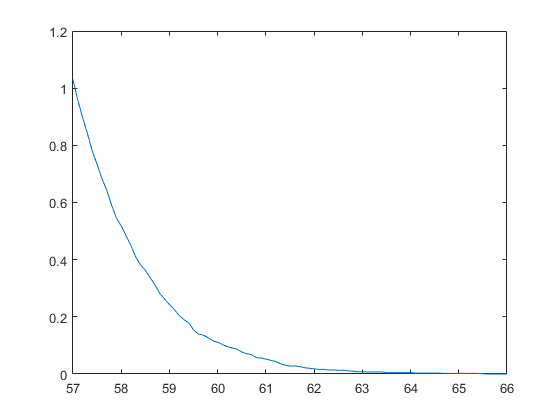



% % Peak Over Threshold
% DMaxPOT = D(D > COv);
% [DMaxPOTeCDF, DMaxPOTR] = ecdf(DMax); DMaxPOTR = DMaxPOTR';
% 
% % Do the same for Parento with POT data
% % Create function to solve for parameters of GEV distribution fit to tail
% fnPar = @(param) sum((gpcdf(DMaxPOTR(COi:end),param(1),param(2),param(3)) - DMaxeCDF(COi:end)').^2);
% % Use gevfit to generate an initial guess
% B = gevfit(DMax);
% % Solve for parameters using fminsearch
% A =  fminsearch(fnGEV,B);

% Try to make the normalized upcrossing graph (Figure 2)
x = 50:0.1:70;
% Average number of times x is exceeded in each day in D
%for i = 1:size(D,2)
    for j = 1:length(x)
        %Up(j) = sum(D(:,i) > x(j));
        Up(j) = sum(sum(D > x(j)))/1000;
    end   
%end

figure
plot(x,Up)
xlim([57 66])

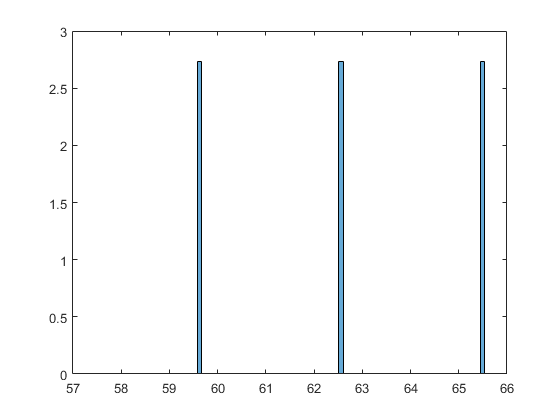


figure
histogram(Up(Up>57),100,'normalization','pdf')
xlim([57 66])





% Legacy... try Matlab's built in Gumbel (extreme value) probability paper plot
% % A = probplot('extreme value',DMax);


% Legacy... used to display normal curve approximation of all maximums (no tail fit)
% % % Fit maximums to normal distribution
% % npd = fitdist(DMax,'normal');
% % x = 50:0.1:70;
% % y = pdf(npd,x);
% % hold on
% % yyaxis left
% % plot(x,y,'r-')
% % text(45,0.3,sprintf('Mu: %.3f',npd.mu),'FontSize',11,'FontWeight','bold','Color','k')
% % text(45,0.275,sprintf('Sigma: %.3f',npd.sigma),'FontSize',11,'FontWeight','bold','Color','k')